% 2)
function s = taylor_sin(x, n)
    s = 0;
    for k = 0:n-1
        s = s + ((-1)^k * x^(2*k + 1)) / factorial(2*k + 1);
    end
end

function c = taylor_cos(x, n)
    c = 0;
    for k = 0:n-1
        c = c + ((-1)^k * x^(2*k)) / factorial(2*k);
    end
end

x = (13*pi)/3; % unghi
n = 5; % nr termeni
aprox_sin = taylor_sin(x, n);
aprox_cos = taylor_cos(x, n);
fprintf('sin(%f) ≈ %f\n', x, aprox_sin);

sin(13.613568) ≈ 30553.073262


fprintf('cos(%f) ≈ %f\n', x, aprox_cos);

cos(13.613568) ≈ 21757.213702



figure
hold on
f_sin = @(x) taylor_sin(x, n);
f_cos = @(x) taylor_cos(x, n);
fplot(f_sin, [-2*pi, 2*pi], 'r')

fplot(f_cos, [-2*pi, 2*pi], 'b')

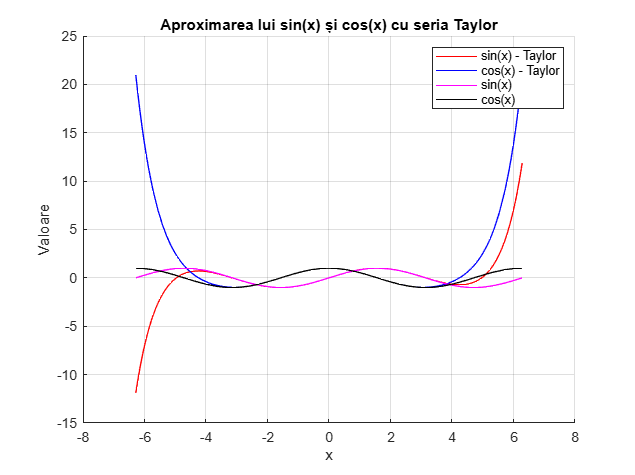


f_sin_act = @(x) sin(x);
f_cos_act = @(x) cos(x);
fplot(f_sin_act, [-2*pi, 2*pi], 'm')
fplot(f_cos_act, [-2*pi, 2*pi], 'black')

legend('sin(x) - Taylor', 'cos(x) - Taylor', 'sin(x)', 'cos(x)')
xlabel('x')
ylabel('Valoare')
title('Aproximarea lui sin(x) și cos(x) cu seria Taylor')
grid on
hold off



% 4)
function [sign_bit, exponent_bits, mantissa_bits] = float_components(num)
    % Determină clasa de precizie a numărului
    if isa(num, 'single')
        bits = 32;
        exponent_length = 8;
        mantissa_length = 23;
        num_cast = typecast(num, 'uint32'); % Convertim single în uint32
    elseif isa(num, 'double')
        bits = 64;
        exponent_length = 11;
        mantissa_length = 52;
        num_cast = typecast(num, 'uint64'); % Convertim double în uint64
    else
        error('Numărul trebuie să fie de tip single sau double.');
    end
    
    % Convertim numărul într-un vector de biți
    binary_representation = dec2bin(num_cast, bits);
    
    % Extragem componentele
    sign_bit = binary_representation(1);
    exponent_bits = binary_representation(2:1+exponent_length);
    mantissa_bits = binary_representation(2+exponent_length:end);
end


[sign_bit, exponent_bits, mantissa_bits] = float_components(single(3.14))

sign_bit = '0'

exponent_bits = '10000000'

mantissa_bits = '10010001111010111000011'